# `フィルタバンク理論に基づく畳込み辞書学習`

# `～ 構造制約を利用した畳込みネットワーク構築 ～`

## `村松正吾（新潟大学工学部工学科電子情報通信プログラム）`

`電子情報通学会　基礎・境界ソサイエティ　Fundamentals Review （掲載予定）`

`動作環境：MATLAB R2023a`

### 準備

clear 
close all

nsoltDic = ""; % "nsoltdictionary_20230617111056377" 

isCodegen = false; % コード生成
setup(isCodegen)

SaivDr-4.2.2.2 exits.
Skip code generation


### パラメータ設定

- ブロックサイズ 

- 冗長度

- スパース度

% Block size
szBlk = [ 8 8 ];

% Redundancy ratio for RICA/K-SVD
redundancyRatio = 5/3;

% Sparsity ratio 
sparsityRatio = 3/64;

## 画像の読込

- 
$$\mathbf{y}\in\mathbb{R}^{N}$$


% 原画像の準備
file_yorg = "../data/yorg.png";
if ~exist(file_yorg,'file')
    unzip('http://www.ess.ic.kanagawa-it.ac.jp/std_img/monoimage2/Mono-Image2.zip','../results')
    yfull = imread('../results/Mono-Image2/512X512/barbara512.bmp');
    ycrop = yfull(1:192,end-255:end);
    imwrite(ycrop,file_yorg)
end

% 原画像の読み込み
yorg = im2double(imread(file_yorg));
szOrg = size(yorg);

画像表示

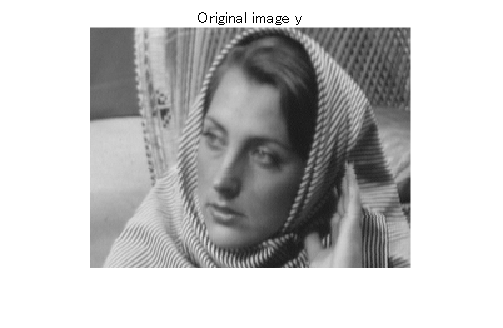

figure
imshow(yorg);
title('Original image y')

零平均化

%ymean = mean(y,"all");
%y = yorg - ymean;
meansubtract = @(x) x-mean(x,"all");
y = meansubtract(yorg);

## 離散コサイン変換（DCT）

    
$$[\mathbf{C}_M]_{k,n}=\sqrt{\frac{2}{M}} \alpha_k\cos\frac{k(n+1∕2)\pi}{M},\ k,n=0,1,\cdots,M-1$$


        
$$\alpha_k=\left\{\begin{array}{ll} \frac{1}{\sqrt{2}} & k=0 \\1 & k=1,2,\cdots,M-1\end{array}\right.$$


#### 基底画像

        
$$\mathbf{B}_{k,\ell}=\mathbf{C}_M^{-1}\mathbf{E}_{k,\ell}\mathbf{C}_M^{-T},\ k,\ell=0,1,\cdots,M-1$$


        
$$\mathbf{E}_{k,\ell}= \mathbf{e}_k\mathbf{e}_\ell^T$$


basisImagesDct = zeros(szBlk(1),szBlk(2),prod(szBlk));
iBasis = 1;
for iRow=1:szBlk(1)
    for iCol=1:szBlk(2)
        E = zeros(szBlk);
        E(iRow,iCol) = 1;
        basisImagesDct(:,:,iBasis) = idct2(E,szBlk(1),szBlk(2));
        iBasis = iBasis + 1;
    end
end

#### 基底画像の表示

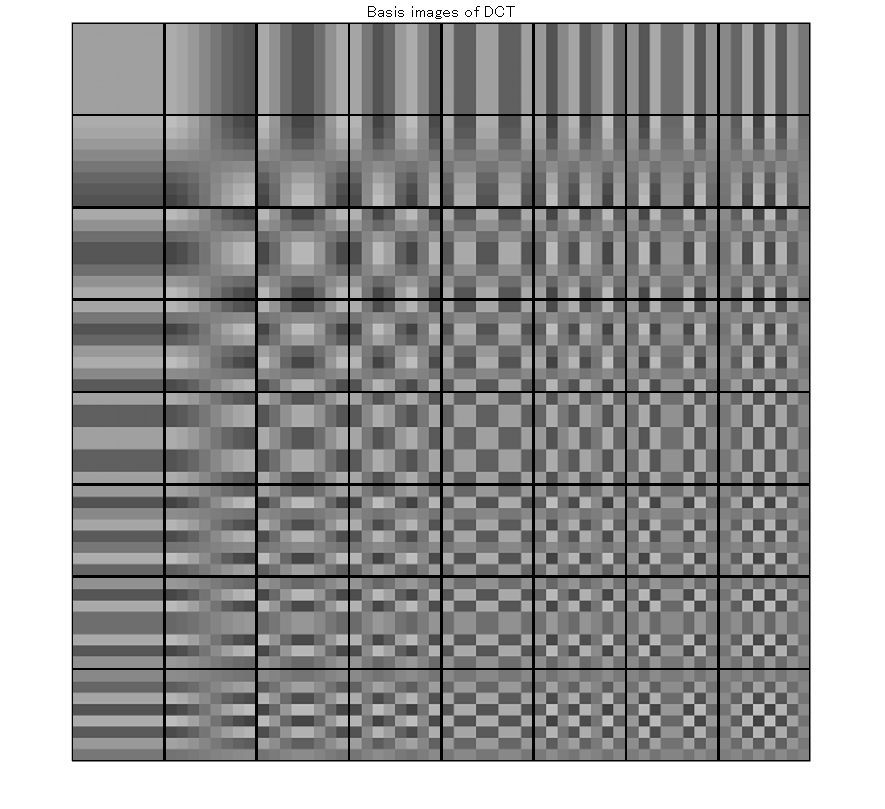

figure
montage(imresize(basisImagesDct,8,'nearest')+.5,'BorderSize',[2 2])
title('Basis images of DCT')

#### ブロックDCTによる合成処理とその随伴処理の定義

syn_blkdct = @(x) blockproc(x,szBlk,@(block_struct) idct2(block_struct.data));
adj_blkdct = @(y) blockproc(y,szBlk,@(block_struct) dct2(block_struct.data));

随伴関係の確認

x = adj_blkdct(y);
v = randn(size(x));
u = syn_blkdct(v);
assert(abs(dot(y(:),u(:))-dot(x(:),v(:)))<1e-9)

## 主成分分析（PCA）

#### 問題設定:

`直交性と次元削減`

    
$$\Phi=\mathbf{I}_M, \forall b, \forall p,\Vert{\mathbf{x}_b}\Vert_0\le p<M$$


`を制約条件とした最小自乗問題`

    
$$\{\hat{\mathbf{\Phi}},\{ \hat{\mathbf{x}}_b \}_b\}=\arg\min_{\{\mathbf{\Phi},\{\mathbf{x}_b\}_b\}}\frac{1}{2S}\sum_{b=1}^{S}\|\mathbf{y}_b-\mathbf{\Phi}{\mathbf{x}}_b\|_2^2$$


`を解く．上式は等価的に`

    
$$\hat{\mathbf{\Phi}}=\arg \max _{\mathbf{\Phi}} \mathrm{tr}\left(\mathbf{\Phi}_{:, 0:p-1}^\textsf{T}\hat{\mathbf{\Sigma}}_{y} \mathbf{\Phi}_{:,0:p-1}\right)\ \mathrm{ s.t. }\ \mathbf{\Phi}^\textsf{T} \mathbf{\Phi}=\mathbf{I}_{M}$$


`と表現できる．`ただし， $\widehat{\mathbf{\Sigma}}_{y}$は 観測ベクトル $\{\mathbf{y}_b\}_b$ （零平均を仮定）の標本分散共分散行列である．

#### 解:

固有値分解

        
$$\widehat{\mathbf{\Phi}}^\textsf{T}\widehat{\mathbf{\Sigma}_y}\widehat{\mathbf{\Phi}}=\mathbf{\Lambda}
$$


ただし， $\mathbf{\Lambda}=\mathrm{diag}(\lambda_1,\lambda_2,\cdots,\lambda_M)$． $\lambda_1\geq\lambda_2\geq\cdots\lambda_M$ は $\widehat{\mathbf{\Sigma}}_{y}$の固有値．

#### 画像 $\mathbf{y}$からのデータ行列 $\mathbf{Y}$ の生成 

標本平均ブロックを引く代わりに，予め零平均化したデータで学習

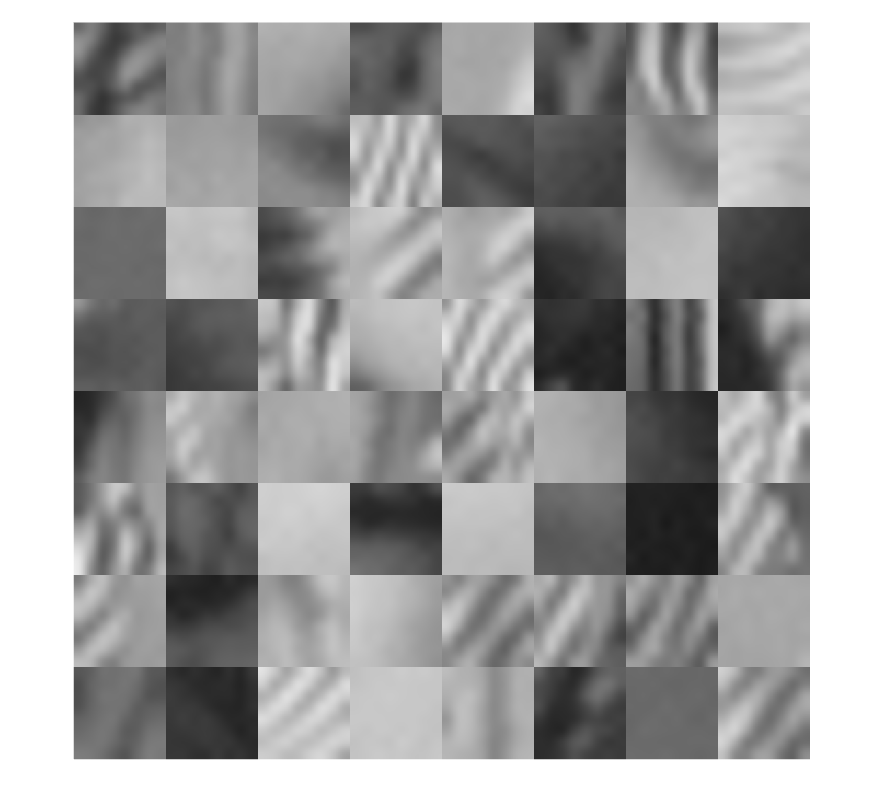

nPatches = 20*prod(szOrg./szBlk); % PCA/RICA/K-SVD 学習用のパッチをランダム抽出
npos = randsample(prod(szOrg-szBlk),nPatches);
ybs = zeros(szBlk(1),szBlk(2),nPatches,'like',y);
szSrchy = szOrg(1)-szBlk(1);
for iPatch = 1:nPatches
    ny_ = mod(npos(iPatch)-1,szSrchy)+1;
    nx_ = floor((npos(iPatch)-1)/szSrchy)+1;
    ybs(:,:,iPatch) = y(ny_:ny_+szBlk(1)-1,nx_:nx_+szBlk(2)-1);
end
figure
montage(ybs+0.5,'Size',[8 8]);

drawnow

Y = reshape(ybs,prod(szBlk),[]);


標本分散共分散行列 $\widehat{\mathbf{\Sigma}}_{y}$の計算 

SigmaY = cov(Y.');

標本分散共分散行列 $\widehat{\mathbf{\Sigma}}_{y}$の固有値分解 

[Phi_pca,Lambda] = eig(SigmaY);

固有値 $\lambda$ の大きさの降順に列ベクトルをソート (Sorting column vectors in the descending order of the eigenvalues $\lambda$)

[~,idx] = sort(diag(Lambda),'descend');
Phi_pca = Phi_pca(:,idx);

固有ベクトルを基底画像に変換

nBases = prod(szBlk);
basisImagesPca = zeros(szBlk(1),szBlk(2),nBases);
for iBasis = 1:nBases
    basisImagesPca(:,:,iBasis) = reshape(Phi_pca(:,iBasis),szBlk(1),szBlk(2));
end

#### 基底画像の表示（辞書）

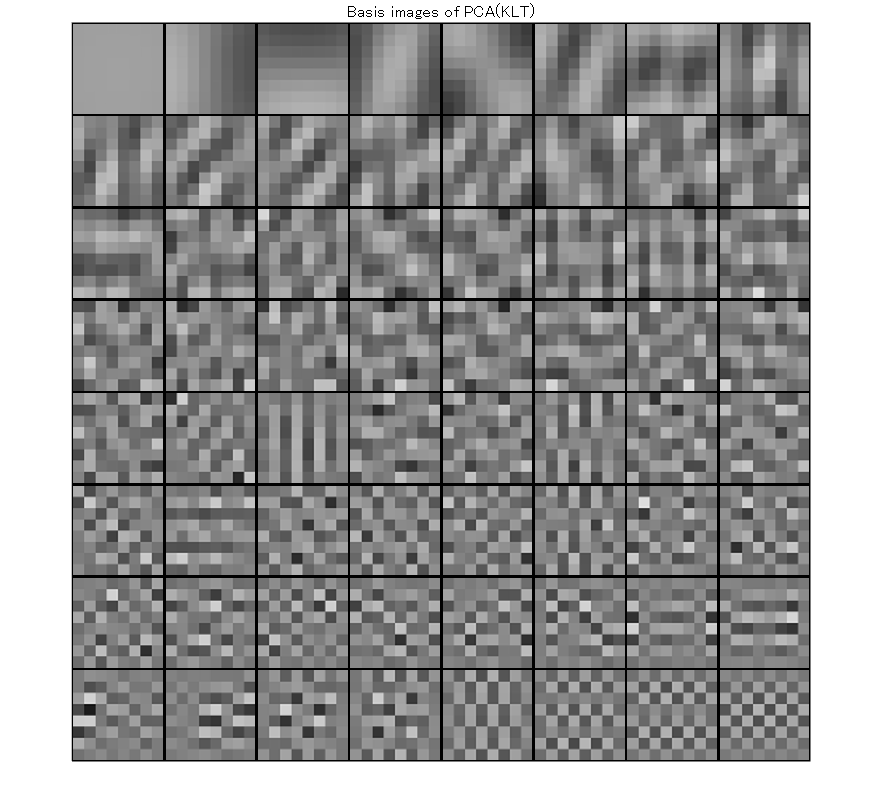

figure
montage(imresize(basisImagesPca,8,'nearest')+.5,'BorderSize',[2 2])
title('Basis images of PCA(KLT)')

#### ブロックPCAによる合成処理とその随伴処理の定義

syn_blkpca = @(x) col2im(Phi_pca*x,szBlk,szOrg,"distinct");
adj_blkpca = @(y) Phi_pca.'*im2col(y,szBlk,"distinct");

随伴関係の確認

x = adj_blkpca(y);
v = randn(size(x));
u = syn_blkpca(v);
assert(abs(dot(y(:),u(:))-dot(x(:),v(:)))<1e-9)

## 再構成独立成分分析（RICA）

#### 問題設定:

        
$$\widehat{\mathbf{\Phi}}=\arg \min _{\mathbf{\Phi}} \frac{1}{2S}\sum_{b=1}^S\|\mathbf{y}_b-\mathbf{\Phi}\mathbf{\Phi}^\textsf{T}\mathbf{y}_b\|_2^2+\frac{\alpha}{S}\sum_{b=1}^{S}\rho(\mathbf{\Phi}^\textsf{T}\mathbf{y}_b)
$$


            
$$=\arg \min _{\mathbf{\Phi}} \frac{(2\alpha)^{-1}}{S}\sum_{b=1}^S\|\mathbf{y}_b-\mathbf{\Phi}\mathbf{\Phi}^\textsf{T}\mathbf{y}_b\|_2^2+\frac{1}{S}\sum_{b=1}^{S}\rho(\mathbf{\Phi}^\textsf{T}\mathbf{y}_b)$$


ただし，  $\{\mathbf{y}_n\}_n\subset\mathbb{R}^{M}$,  $\mathbf{\Phi}=(\mathbf{\phi}_1,\mathbf{\phi}_2,\cdots,\mathbf{\phi}_P)\in\mathbb{R}^{M\times P}$, $M\geq P$ である．

#### 参考文献:

Le, Quoc V., Alexandre Karpenko, Jiquan Ngiam, and Andrew Y. Ng. “ICA with Reconstruction Cost for Efficient Overcomplete Feature Learning.” Advances in Neural Information Processing Systems. Vol. 24, 2011, pp. 1017–1025. https://papers.nips.cc/paper/4467-ica-with-reconstruction-cost-for-efficient-overcomplete-feature-learning.pdf. 

パラメータ設定

- 繰返し回数 (Number of iterations)

- 正則化パラメータ (Regularization parameter)

% Number of iterations
nItersRica = 1e5; 
% Regularization parameter
alpha = 2e-3;

コントラスト関数の例

        
$$\rho(\mathbf{\Phi}^\textsf{T}\mathbf{y})\colon = \frac{1}{2}\sum_{p=1}^{P}\log\circ\cosh(2\mathbf{\phi}_p^\textsf{T}\mathbf{y})$$


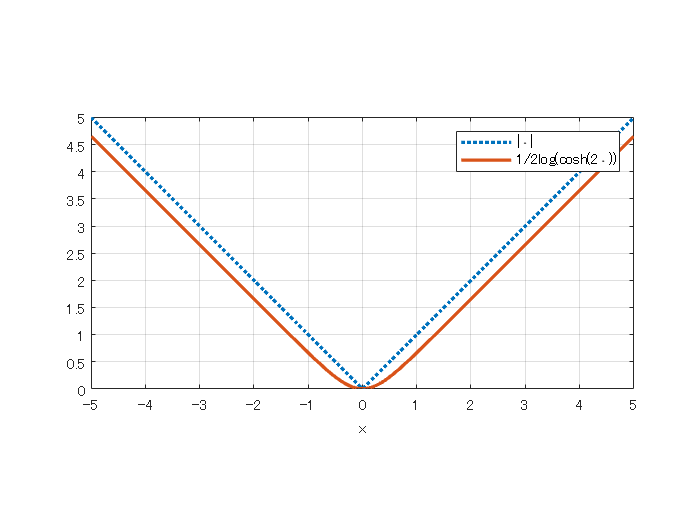

figure
fplot(@(x) abs(x),[-5 5],':','LineWidth',2,'DisplayName','|\cdot|')
hold on
fplot(@(x) log(cosh(2*x))/2,[-5 5],'-','LineWidth',2,'DisplayName','1/2log(cosh(2\cdot))')
xlabel('x')
legend
grid on
axis equal
hold off

要素画像の数 

nDims = prod(szBlk);
nAtoms = ceil(redundancyRatio*nDims);

辞書 $\mathbf{\Phi}$の初期化

- 二次元離散コサイン変換

- ランダム

Phi_rica = randn(nDims,nAtoms);
Phi_rica = Phi_rica/norm(Phi_rica,'fro');
for iAtom = 1:nDims
    delta = zeros(szBlk);
    delta(iAtom) = 1;
    Phi_rica(:,iAtom) = reshape(idct2(delta),nDims,1);
end

要素ベクトルを要素画像に変換 

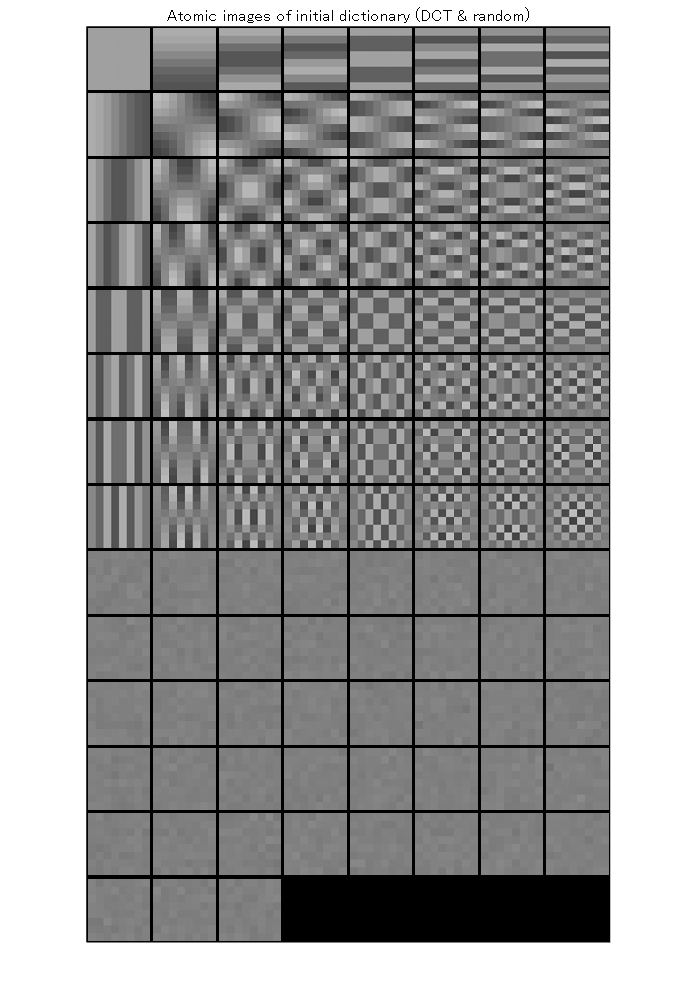

atomicImagesRica = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesRica(:,:,iAtom) = reshape(Phi_rica(:,iAtom),szBlk(1),szBlk(2));
end
figure
montage(imresize(atomicImagesRica,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of initial dictionary (DCT & random)')

#### 再構成 ICA オブジェクトの作成

PCAに合わせて予め零平均化したデータで学習

model = rica(Y.',nAtoms,...
    'IterationLimit',nItersRica,...
    'ContrastFcn','logcosh',...
    'InitialTransformWeight',Phi_rica,...
    'Lambda',1/(2*alpha));

コスト評価のグラフ 

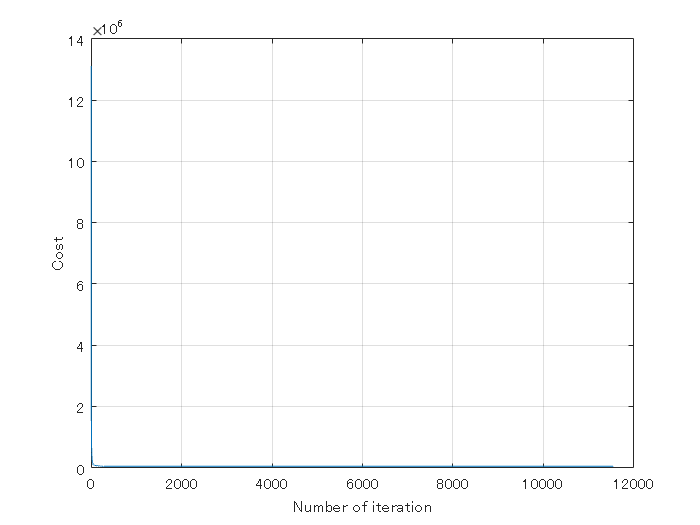

info = model.FitInfo;
figure
plot(info.Iteration,info.Objective)
xlabel('Number of iteration')
ylabel('Cost')
grid on

要素ベクトルを要素画像に変換

Phi_rica = model.TransformWeights;
atomicImagesRica = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesRica(:,:,iAtom) = reshape(Phi_rica(:,iAtom),szBlk(1),szBlk(2));
end

#### 要素画像の表示（辞書）

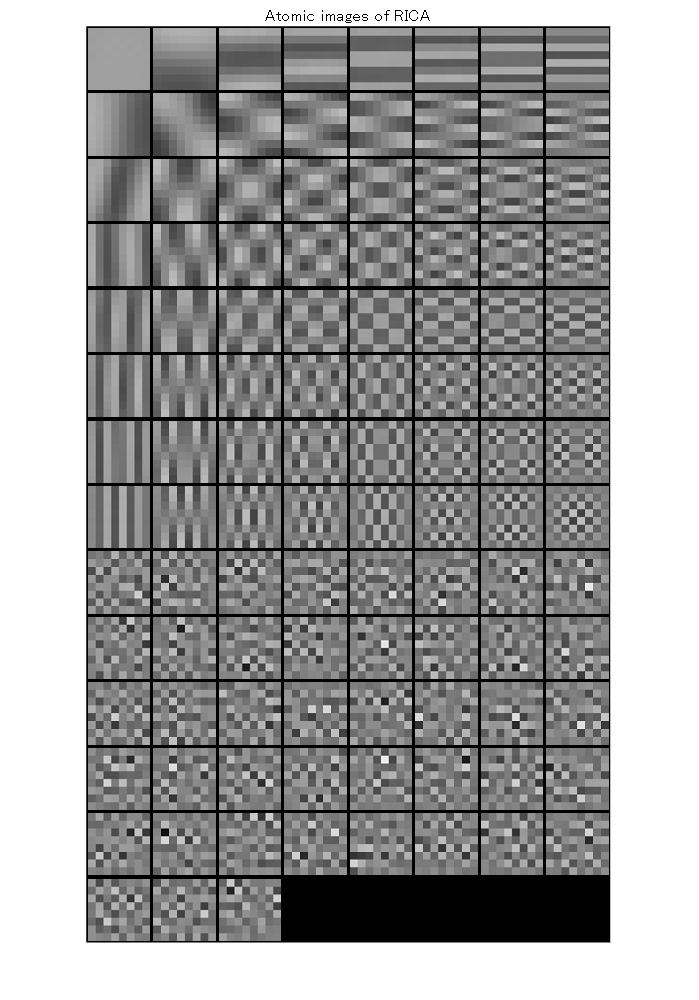

figure
montage(imresize(atomicImagesRica,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of RICA')

#### ブロックRICAによる合成処理とその随伴処理の定義

syn_blkrica = @(x) col2im(Phi_rica*x,szBlk,szOrg,"distinct");
adj_blkrica = @(y) Phi_rica.'*im2col(y,szBlk,"distinct");

随伴関係の確認

x = adj_blkrica(y);
v = randn(size(x));
u = syn_blkrica(v);
assert(abs(dot(y(:),u(:))-dot(x(:),v(:)))<1e-9)

## K-特異値分解

パラメータ設定

- 繰返し回数 (Number of iterations)

% Number of iterations
nItersKsvd = 5e3;

#### 問題設定 (Problem setting):

    
$$\{\hat{\mathbf{\Phi}},\{ \hat{\mathbf{x}}_b \}\}=\arg\min_{\{\mathbf{\Phi},\{\mathbf{x}_b\}\}}\frac{1}{2S}\sum_{b=1}^{S}\|\mathbf{y}_b-\mathbf{\Phi}\hat{\mathbf{x}}_b\|_2^2,\ \quad\mathrm{s.t.}\ \forall b, \|\mathbf{x}_b\|_0\leq K$$$


#### アルゴリズム :

スパース近似ステップと辞書更新ステップを繰返す．

- スパース近似ステップ 

                
$$\hat{\mathbf{x}}_b=\arg\min_{\mathbf{x}} \frac{1}{2}\|\mathbf{y}_b-\hat{\mathbf{\Phi}}\mathbf{x}\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{x}\|_0\leq K$$


- 辞書更新ステップ 

                
$$\hat{\mathbf{\Phi}}=\arg\min_{\mathbf{\Phi}}\frac{1}{2S}\sum_{b=1}^{S}\|\mathbf{y}_b-\mathbf{\Phi}\hat{\mathbf{x}}_b\|_2^2=\arg\min_{\mathbf{\Phi}}\frac{1}{2S}\left\|\left(\mathbf{Y}-\sum_{p\neq k}\mathbf{\phi}_p\hat{\mathbf{X}}_{p,\colon}\right)-\mathbf{\phi}_k\hat{\mathbf{X}}_{k,\colon}\right\|_F^2$$


係数の数 

nCoefsKsvd = max(floor(sparsityRatio*nDims),1);

辞書 $\mathbf{\Phi}$の初期化 

- 二変量離散コサイン変換

- ランダム 

Phi_ksvd = randn(nDims,nAtoms);
Phi_ksvd = Phi_ksvd/norm(Phi_ksvd,'fro');
for iAtom = 1:nDims
    delta = zeros(szBlk);
    delta(iAtom) = 1;
    Phi_ksvd(:,iAtom) = reshape(idct2(delta),nDims,1);
end

要素ベクトルを要素画像に変換

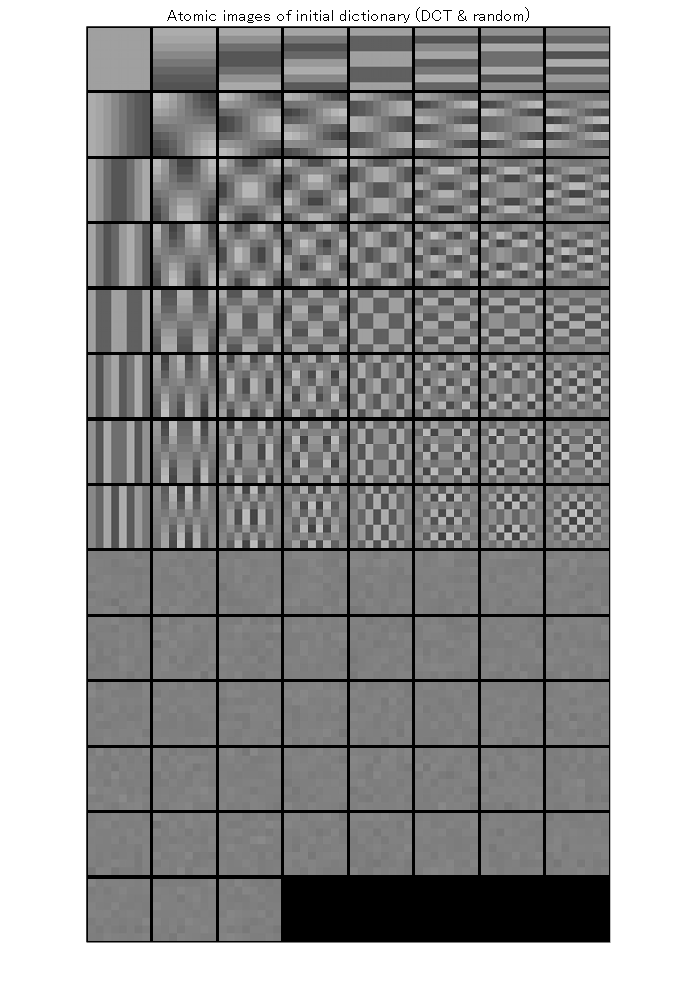

atomicImagesKsvd = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesKsvd(:,:,iAtom) = reshape(Phi_ksvd(:,iAtom),szBlk(1),szBlk(2));
end
figure
montage(imresize(atomicImagesKsvd,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of initial dictionary (DCT & random)')

#### スパース近似ステップと辞書更新ステップの繰り返し

- スパース近似： 直交マッチング追跡 (OMP)

- 辞書更新： 特異値分解(SVD)と1-ランク近似 

辞書更新の内容

- 
$$k\leftarrow 1$$


- 誤差行列 $\mathbf{E}_k$ を定義：$\mathbf{E}_k\colon = \mathbf{Y}-\sum_{p\neq k}\mathbf{\phi}_p\hat{\mathbf{X}}_{p,\colon}$

- データ行 $\hat{\mathbf{X}}_{k,\colon}$の非零値を抽出する行列 $\mathbf{\Omega}_k$を定義： $\hat{\mathbf{X}}_{k,\colon}^R=\hat{\mathbf{X}}_{k,\colon}\mathbf{\Omega}_k \Leftrightarrow \hat{\mathbf{X}}_{k,\colon}^R\mathbf{\Omega}_k^T=\hat{\mathbf{X}}_{k,\colon}$

- 誤差行列 $\mathbf{E}_k$ を行列 $\mathbf{\Omega}_k$で縮退： $\mathbf{E}_k^R \colon=\mathbf{E}_k\mathbf{\Omega}_k$

- 縮退した誤差行列$\mathbf{E}_k^R$を特異値分解：$\mathbf{E}_k^R =\mathbf{U}\mathbf{S}\mathbf{V}^T
=\left(\mathbf{u}_1,\mathbf{u}_2,\cdots,\mathbf{u}_r\right)\mathrm{diag}(\sigma_1,\sigma_2,\cdots,\sigma_r)\left(\mathbf{v}_1,\mathbf{v}_2,\cdots,\mathbf{v}_r\right)^T$

- 要素ベクトル $\mathbf{\phi}_k$ を更新： $\mathbf{k}\leftarrow \mathbf{u}_1$

- データ行$\hat{\mathbf{X}}_{k,\colon}$を更新： $\hat{\mathbf{X}}_{k,\colon}\leftarrow \sigma_1\mathbf{v}_{1}^T$

- 
$$k\leftarrow k+1$$


- $k\leq N$ ならば 2. へ $k>N$ ならば終了

ただし， $\sigma_1$ を最大特異値とする．

#### 交互ステップの繰返し計算

PCAに合わせて予め零平均化したデータで学習

cost = zeros(1,nItersKsvd);
nSamples = size(Y,2);
for iIter = 1:nItersKsvd
    X = zeros(nAtoms,nSamples);
    % Sparse approximation
    for iSample = 1:nSamples
        y_ = Y(:,iSample);
        x = omp(y_,Phi_ksvd,nCoefsKsvd);
        X(:,iSample) = x;
    end
    % Dictionary update
    for iAtom = 1:nAtoms
        idxset = setdiff(1:nAtoms,iAtom);
        xk = X(iAtom,:);
        suppk = find(xk);
        %
        Ekred = Y(:,suppk)-Phi_ksvd(:,idxset)*X(idxset,suppk);
        %
        if ~isempty(suppk)
            [U,S,V] = svd(Ekred,'econ');
            ak = U(:,1);
            xkred = S(1,1)*V(:,1)';
            %
            Phi_ksvd(:,iAtom) = ak;
            X(iAtom,suppk) = xkred;
        end
    end
    cost(iIter) = (norm(Y-Phi_ksvd*X,'fro')^2)/(2*nSamples);
end

コスト評価のグラフ 

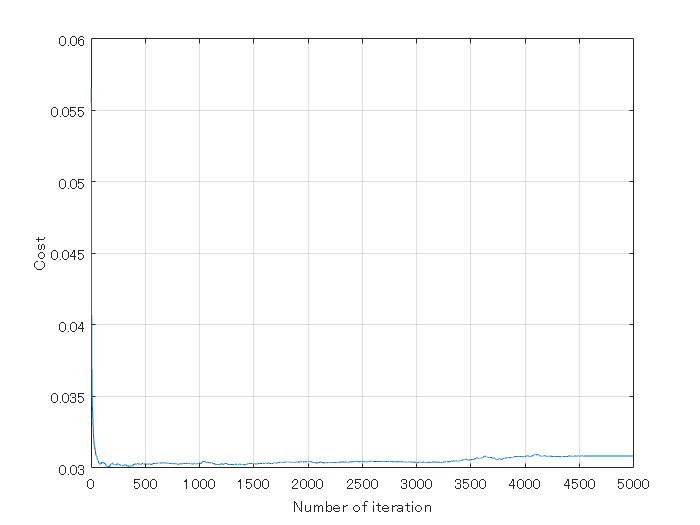

figure
plot(cost)
xlabel('Number of iteration')
ylabel('Cost')
grid on

要素ベクトルを要素画像に変換 

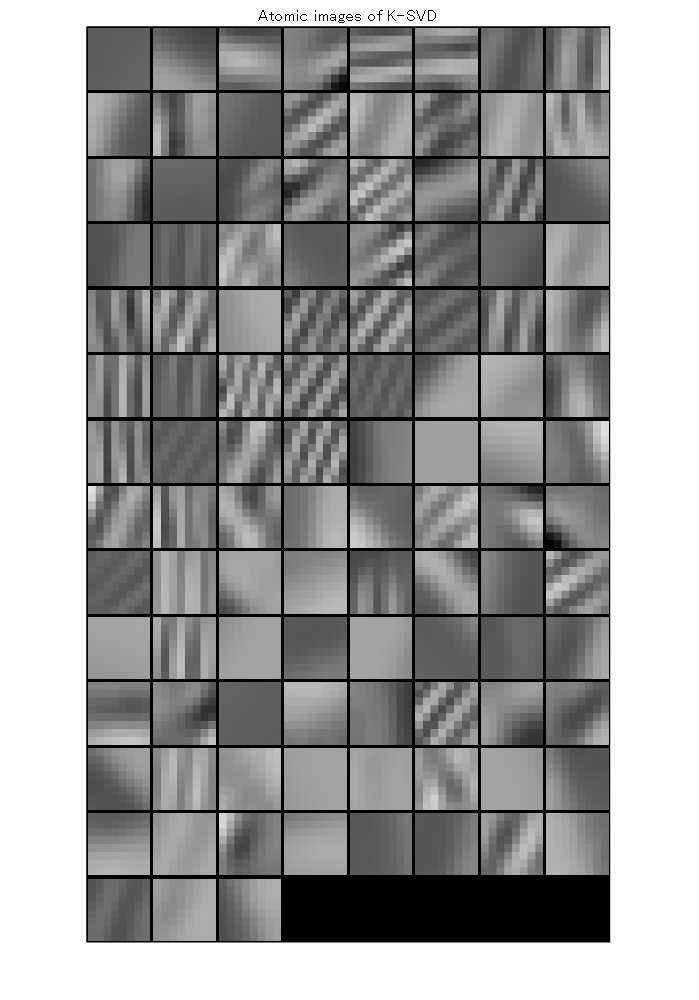

atomicImagesKsvd = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImagesKsvd(:,:,iAtom) = reshape(Phi_ksvd(:,iAtom),szBlk(1),szBlk(2));
end
figure
montage(imresize(atomicImagesKsvd,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of K-SVD')

#### ブロックK-特異値分解による合成処理とその随伴処理の定義

syn_blkksvd = @(x) col2im(Phi_ksvd*x,szBlk,szOrg,"distinct");
adj_blkksvd = @(y) Phi_ksvd.'*im2col(y,szBlk,"distinct");

随伴関係の確認

x = adj_blkksvd(y);
v = randn(size(x));
u = syn_blkksvd(v);
assert(abs(dot(y(:),u(:))-dot(x(:),v(:)))<1e-9)

## 2変量ラティス構造冗長フィルタバンク

例として，（偶対称チャネルと奇対称チャネルが等しい）偶数チャネル、偶数のポリフェーズ次数をもつタイプI非分離冗長重複変換(NSOLT)

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{n_\mathrm{h}=1}^{\nu_\mathrm{h}/2}
{\mathbf{V}_{2n_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{n_{\mathrm{v}}=1}^{\nu_\mathrm{v}/2}{\mathbf{V}_{2n_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2n_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^\textsf{T}(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


を採用する．ただし，

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  分析フィルタバンクのType-I ポリフェーズ行列

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: 合成フィルタバンクのType-II ポリフェーズ行列

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: Z-変換の変数

- $\nu_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$:方向 $d$ のポリフェーズ次数(重複ブロック数)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, $\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$は直交行列

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【References】 

- [Overview of Filter Banks - MATLAB & Simulink - MathWorks 日本](https://jp.mathworks.com/help/dsp/ug/overview-of-filter-banks.html)

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

### 2次元画像の階層的分析

$R_M^P(\tau)$ をツリーレベル $\tau$の階層構造フィルタバンクの冗長度とすると、

     
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


となる．

#### パッケージダウンロード

% SaivDr パッケージバージョン
SAIVDR_VER = "4.2.2.2";
SAIVDR_DIR = "SaivDr-"+SAIVDR_VER;
if ~exist(SAIVDR_DIR,"dir")
    unzip("https://github.com/msiplab/SaivDr/archive/refs/tags/"+SAIVDR_VER+".zip")
else
    disp(SAIVDR_DIR+" exits.")
end

SaivDr-4.2.2.2 exits.


ccd = cd(SAIVDR_DIR);
setpath
if isempty(dir("./mexcodes/fcn_*"))
    mybuild
else
    disp("MEX files exist.")
end

MEX files exist.


cd(ccd)

#### 構成パラメータ設定

%{
% Decimation factor (Strides)
decFactor = [2 2]; % [μv μh] 

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [3 3]; % [Ps Pa] (Ps=Pa)

% Number of tree levels
nLevels = 3; 

% Polyphase Order
ppOrder = [4 4]; 
%}

%%{
% Decimation factor (Strides)
decFactor =  [4 4]; % [μv μh] 

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [13 13]; % [Ps Pa] (Ps=Pa)

% Number of tree levels
nLevels = 2; 

% Polyphase Order
ppOrder = [2 2];
%%}

%{
% Decimation factor (Strides)
decFactor =  [8 8]; % [μv μh] 

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [53 53]; % [Ps Pa] (Ps=Pa)

redundancyNsolt = 1.6641


% Number of tree levels
nLevels = 1; 

% Polyphase Order

szFilters =     56    56


ppOrder = [2 2];
%}


szPatchTrn =     64    64


% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancyNsolt = ...

nSubImgs = 240

    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))
assert(redundancyNsolt<redundancyRatio)


noDcLeakage = logical
   1



$$L_\mathrm{v}\times L_\mathrm{h}=\left(\mu_\mathrm{v}^{\tau}+{\nu}_\mathrm{v}\frac{\mu_\mathrm{v}(\mu_\mathrm{v}^{\tau}-1)}{\mu_\mathrm{v}-1}\right) \times\left(\mu_\mathrm{h}^{\tau}+\nu_\mathrm{h}\frac{\mu_\mathrm{h}(\mu_\mathrm{h}^{\tau}-1)}{\mu_\mathrm{h}-1}\right)$$
 

maxIters = 400

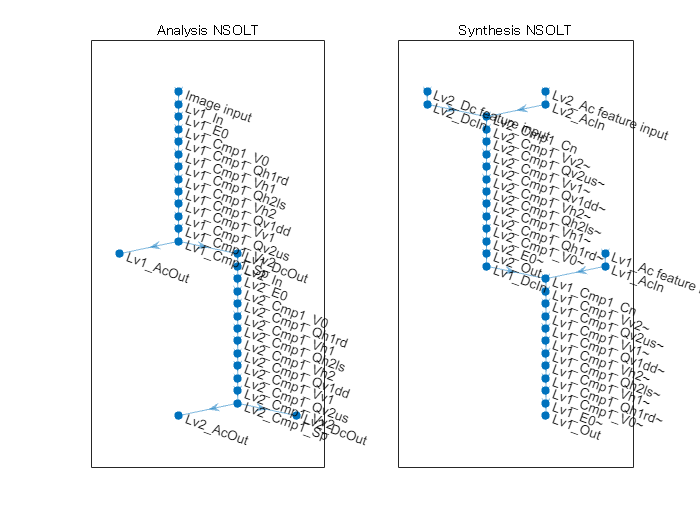

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 6.2082e-11"



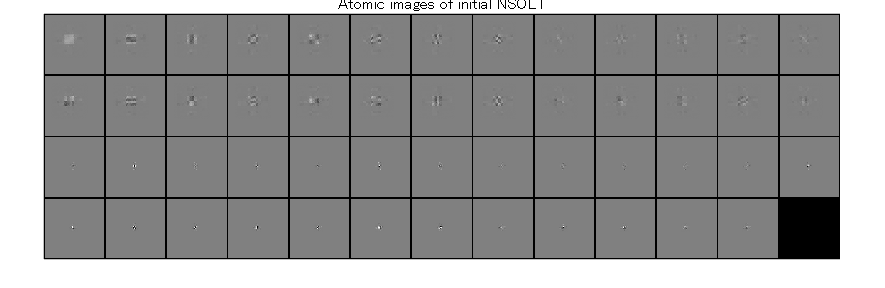

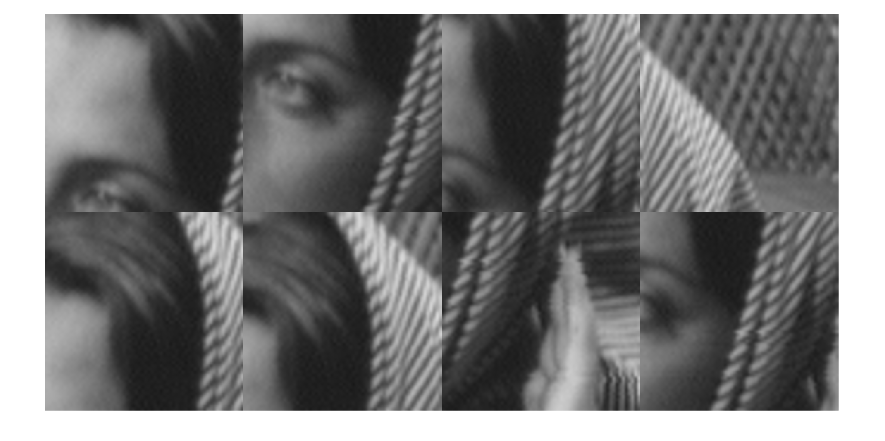

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１３　｜　　　　　　　　　３．５４　｜　　　　　　　６．３　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０５：４１　｜　　　　　　　　　３．０７　｜　　　　　　　４．７　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１１：１５　｜　　　　　　　　　３．１３　｜　　　　　　　４．９　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１６：４３　｜　　　　　　　　　３．３０　｜　　　　　　　５．４　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２２：４２　｜　　　　　　　　　３．１４　｜　　　　　　　４．９　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：２８：３３　｜　　　　　　　　　２．９３　｜　　　　　　　４．３　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３４：４９　｜　　　　　　　　　３．１０　｜　　　　　　　４．８　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：４１：１３　｜　　　　　　　　　２．８６　｜　　　　　　　４．１　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４７：２０　｜　　　　　　　　　２．９４　｜　　　　　　　４．３　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 3.324e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１４　｜　　　　　　　　　２．９７　｜　　　　　　　４．４　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０６：２２　｜　　　　　　　　　２．８１　｜　　　　　　　４．０　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１１：５２　｜　　　　　　　　　２．６３　｜　　　　　　　３．５　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１７：２５　｜　　　　　　　　　２．７０　｜　　　　　　　３．７　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２３：０１　｜　　　　　　　　　２．９５　｜　　　　　　　４．４　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：２８：３３　｜　　　　　　　　　２．５５　｜　　　　　　　３．３　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３４：０９　｜　　　　　　　　　２．８１　｜　　　　　　　３．９　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：３９：４４　｜　　　　　　　　　２．７０　｜　　　　　　　３．６　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４５：１６　｜　　　　　　　　　２．８５　｜　　　　　　　４．１　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 3.8698e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１３　｜　　　　　　　　　２．７４　｜　　　　　　　３．８　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０５：４１　｜　　　　　　　　　２．４６　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１１：５１　｜　　　　　　　　　２．５９　｜　　　　　　　３．３　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１７：５３　｜　　　　　　　　　２．４４　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２３：５５　｜　　　　　　　　　２．８０　｜　　　　　　　３．９　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：３０：０３　｜　　　　　　　　　２．４５　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３６：０５　｜　　　　　　　　　２．６６　｜　　　　　　　３．５　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：４２：０９　｜　　　　　　　　　２．５３　｜　　　　　　　３．２　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４８：１３　｜　　　　　　　　　２．６７　｜　　　　　　　３．６　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 2.7927e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１１　｜　　　　　　　　　２．５７　｜　　　　　　　３．３　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０５：５４　｜　　　　　　　　　２．８５　｜　　　　　　　４．１　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１１：５９　｜　　　　　　　　　２．５５　｜　　　　　　　３．３　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１８：０４　｜　　　　　　　　　２．７６　｜　　　　　　　３．８　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２４：１７　｜　　　　　　　　　２．４５　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：３０：２０　｜　　　　　　　　　２．７０　｜　　　　　　　３．６　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３６：２３　｜　　　　　　　　　２．２０　｜　　　　　　　２．４　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：４２：２５　｜　　　　　　　　　２．９４　｜　　　　　　　４．３　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４８：２７　｜　　　　　　　　　２．７５　｜　　　　　　　３．８　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 2.549e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１３　｜　　　　　　　　　２．４４　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０６：１９　｜　　　　　　　　　２．６１　｜　　　　　　　３．４　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１２：１３　｜　　　　　　　　　２．４３　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１８：００　｜　　　　　　　　　２．５３　｜　　　　　　　３．２　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２４：１３　｜　　　　　　　　　２．８２　｜　　　　　　　４．０　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：３０：１６　｜　　　　　　　　　２．４５　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３６：０７　｜　　　　　　　　　２．４８　｜　　　　　　　３．１　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：４２：１４　｜　　　　　　　　　２．５９　｜　　　　　　　３．４　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４７：４８　｜　　　　　　　　　２．６１　｜　　　　　　　３．４　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 2.4454e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１１　｜　　　　　　　　　２．４５　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０５：５３　｜　　　　　　　　　２．６３　｜　　　　　　　３．４　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１１：４４　｜　　　　　　　　　２．３８　｜　　　　　　　２．８　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１７：２８　｜　　　　　　　　　２．２８　｜　　　　　　　２．６　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２３：０５　｜　　　　　　　　　２．６７　｜　　　　　　　３．６　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：２８：４８　｜　　　　　　　　　２．３８　｜　　　　　　　２．８　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３４：５２　｜　　　　　　　　　２．４１　｜　　　　　　　２．９　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：４０：３０　｜　　　　　　　　　２．５９　｜　　　　　　　３．４　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４６：２５　｜　　　　　　　　　２．５５　｜　　　　　　　３．３　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 2.8741e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１１　｜　　　　　　　　　２．４０　｜　　　　　　　２．９　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０６：０２　｜　　　　　　　　　２．３３　｜　　　　　　　２．７　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１２：１５　｜　　　　　　　　　２．５０　｜　　　　　　　３．１　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１８：２０　｜　　　　　　　　　２．６５　｜　　　　　　　３．５　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２４：３０　｜　　　　　　　　　２．４５　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：３０：３９　｜　　　　　　　　　２．５７　｜　　　　　　　３．３　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３６：３９　｜　　　　　　　　　２．３０　｜　　　　　　　２．６　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：４２：４８　｜　　　　　　　　　２．４３　｜　　　　　　　３．０　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４８：４３　｜　　　　　　　　　２．３９　｜　　　　　　　２．９　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 2.5514e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１３　｜　　　　　　　　　２．３７　｜　　　　　　　２．８　｜　　０．００１０　｜
｜　　　　　　４　｜　　　５０　｜　　　　　００：０６：１３　｜　　　　　　　　　２．５９　｜　　　　　　　３．４　｜　　０．００１０　｜
｜　　　　　　７　｜　　１００　｜　　　　　００：１２：２１　｜　　　　　　　　　２．３５　｜　　　　　　　２．８　｜　　０．００１０　｜
｜　　　　　１０　｜　　１５０　｜　　　　　００：１８：２６　｜　　　　　　　　　２．４８　｜　　　　　　　３．１　｜　　０．００１０　｜
｜　　　　　１３　｜　　２００　｜　　　　　００：２４：３３　｜　　　　　　　　　２．４２　｜　　　　　　　２．９　｜　　０．００１０　｜
｜　　　　　１６　｜　　２５０　｜　　　　　００：３０：３８　｜　　　　　　　　　２．２０　｜　　　　　　　２．４　｜　　０．００１０　｜
｜　　　　　１９　｜　　３００　｜　　　　　００：３６：４１　｜　　　　　　　　　２．３９　｜　　　　　　　２．８　｜　　０．００１０　｜
｜　　　　　２２　｜　　３５０　｜　　　　　００：４２：５２　｜　　　　　　　　　２．０８　｜　　　　　　　２．２　｜　　０．００１０　｜
｜　　　　　２５　｜　　４００　｜　　　　　００：４９：０３　｜　　　　　　　　　２．６２　｜　　　　　　　３．４　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


    "MSE: 2.5752e-14"



Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2


% Filter size [ Ly Lx ]
szFilters = decFactor.^nLevels + ppOrder.*decFactor.*(decFactor.^nLevels-1)./(decFactor-1)

% Patch size for training
szPatchTrn = 2.^nextpow2(szFilters+1) % > [ Ly Lx ]
assert(all(szPatchTrn>szFilters))

% Number of patchs per image
nSubImgs = floor(nPatches*prod(szBlk./szPatchTrn))
assert(nSubImgs > 0)

% No DC-leakage
noDcLeakage = true

#### 辞書の設定

if exist("../data/"+nsoltDic+".mat","file")
    S = load("../data/"+nsoltDic);
    analysisnet = S.analysisnet;
    synthesisnet = S.synthesisnet;
    nLevels_ = extractnumlevels(analysisnet);
    decFactor_ = extractdecfactor(analysisnet);
    nChannels_ = extractnumchannels(analysisnet);

    assert(nLevels==nLevels_)
    assert(all(decFactor==decFactor_))

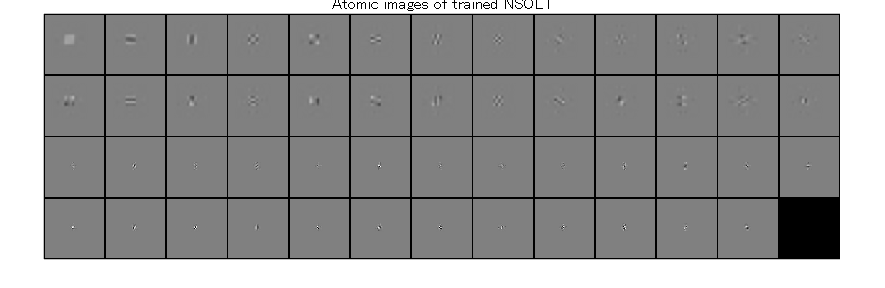

    assert(all(nChannels==nChannels_))
else
    % Number of iterations
    nItersNsolt = 8;

    % Standard deviation of initial angles
    stdInitAng = 1e-1; %pi/6;


    % Mini batch size
    miniBatchSize = 15;

    % Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
    maxEpochs = 25;

    % Number of iterations
    maxIters = nSubImgs/miniBatchSize * maxEpochs

    % Training options
    opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
        ...'Momentum', 0.9000,...
        'InitialLearnRate',1.0e-03,...
        ...'LearnRateScheduleSettings','none',...
        'L2Regularization',0.0, ... 1.0e-04,... 
        ...'GradientThresholdMethod','l2norm',...
        ...'GradientThreshold',Inf,...
        'MaxEpochs',maxEpochs,...30,...
        'MiniBatchSize',miniBatchSize,...128,...
        'Verbose',1,...
        ...'VerboseFrequency',50,...
        ...'ValidationData',[],...
        ...'ValidationFrequency',50,...
        ...'ValidationPatience',Inf,...
        ...'Shuffle','once',...
        ...'CheckpointPath','',...
        ...'ExecutionEnvironment','auto',...
        ...'WorkerLoad',[],...
        ...'OutputFcn',[],...
        'Plots','none',...'training-progress',...
        ...'SequenceLength','longest',...
        ...'SequencePaddingValue',0,...
        ...'SequencePaddingDirection','right',...
        ...'DispatchInBackground',0,...
        'ResetInputNormalization',0);...1

#### 層構造の構築

    import saivdr.dcnn.*
    analysislgraph = fcn_creatensoltlgraph2d([],...
        'InputSize',szPatchTrn,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...
        'NumberOfLevels',nLevels,...
        'NumberOfVanishingMoments',noDcLeakage,...
        'Mode','Analyzer');
    synthesislgraph = fcn_creatensoltlgraph2d([],...
        'InputSize',szPatchTrn,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...
        'NumberOfLevels',nLevels,...
        'NumberOfVanishingMoments',noDcLeakage,...
        'Mode','Synthesizer');

    figure
    subplot(1,2,1)
    plot(analysislgraph)
    title('Analysis NSOLT')
    subplot(1,2,2)
    plot(synthesislgraph)
    title('Synthesis NSOLT')

    % Construction of deep learning network.
    synthesisnet = dlnetwork(synthesislgraph);

    % Initialize
    nLearnables = height(synthesisnet.Learnables);
    for iLearnable = 1:nLearnables
        if synthesisnet.Learnables.Parameter(iLearnable)=="Angles"
            layerName = synthesisnet.Learnables.Layer(iLearnable);
            synthesisnet.Learnables.Value(iLearnable) = ...
                cellfun(@(x) x+stdInitAng*randn(size(x)), ...
                synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
        end
    end

    % Copy the synthesizer's parameters to the analyzer
    synthesislgraph = layerGraph(synthesisnet);
    analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);
    analysisnet = dlnetwork(analysislgraph);

#### 随伴関係（完全再構成）の確認

NSOLTはパーセバルタイト性を満たす．

    nOutputs = nLevels+1;
    x = rand(szPatchTrn,'single');
    s = cell(1,nOutputs);
    dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
    [s{1:nOutputs}] = analysisnet.predict(dlx);
    dly = synthesisnet.predict(s{:});
    display("MSE: " + num2str(mse(dlx,dly)))

#### 要素画像の初期状態

    import saivdr.dcnn.*
    figure
    atomicimshow(synthesisnet,[],2^(nLevels-1))
    title('Atomic images of initial NSOLT')

dicname = "Block DCTwoN"

dicname = "Block DCT"

dicname = "Block PCAwoN"

dicname = "Block PCA"

dicname = "Block RICA"

dicname = "Block K-SVD"

dicname = "NSOLTwoN"

dicname = "NSOLT"

### 訓練画像の準備

画像データストアからランダムにパッチを抽出

PCAに合わせて予め零平均化したデータで学習

    imds = imageDatastore(file_yorg,"ReadFcn",@(x) meansubtract(im2single(imread(x))));
    patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
    figure
    minibatch = preview(patchds);
    responses = minibatch.ResponseImage;
    responses = cellfun(@(x) x + 0.5,responses,'UniformOutput',false);
    figure
    montage(responses,'Size',[2 4]);
    drawnow

### 畳み込み辞書学習

#### 問題設定:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{x}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{x}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{y}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{x}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{x}_n\|_0\leq K,$$$


ただし， $\mathbf{D}_{\mathbf{\theta}}$は設計パラメータベクトル $\mathbf{\theta}}$をもつ畳み込み辞書．

#### アルゴリズム:

スパース近似ステップと辞書更新ステップを繰返す．

- スパース近似ステップ

                
$$\hat{\mathbf{x}}_n=\arg\min_{\mathbf{x}_n}\frac{1}{2} \|\mathbf{y}_n-\hat{\mathbf{D}}\mathbf{x}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{x}_n\|_0\leq K$$


- 辞書更新ステップ

                
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{y}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{x}}_n\|_2^2$$


                
$$\hat{\mathbf{D}}=\mathbf{D}_{\hat{\mathbf{\theta}}$$


#### 採用するスパース近似と辞書更新の手法:

- スパース近似：（正規化なし）繰返しハード閾値処理(IHT)

- 辞書更新： モーメンタム付き確率的勾配降下法(SGD)

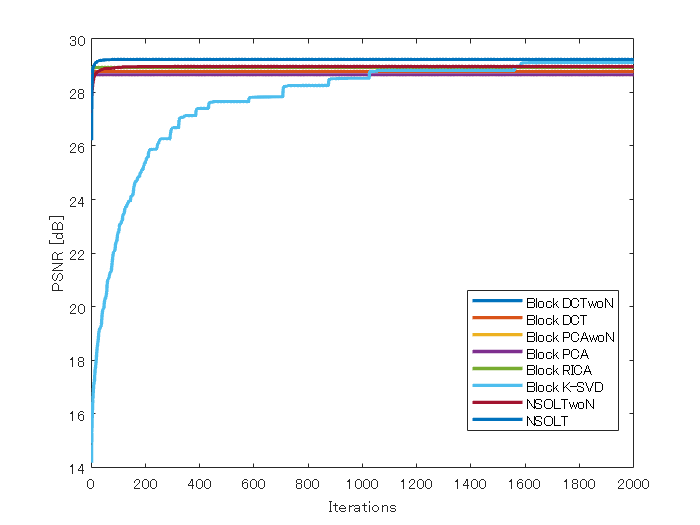

    % Check if IHT works for dlarray
    %x = dlarray(randn(szPatchTrn,'single'),'SSCB');

    %[y,coefs{1:nOutputs}] = iht(x,analysisnet,synthesisnet,sparsityRatio);

#### 辞書学習の繰返し計算

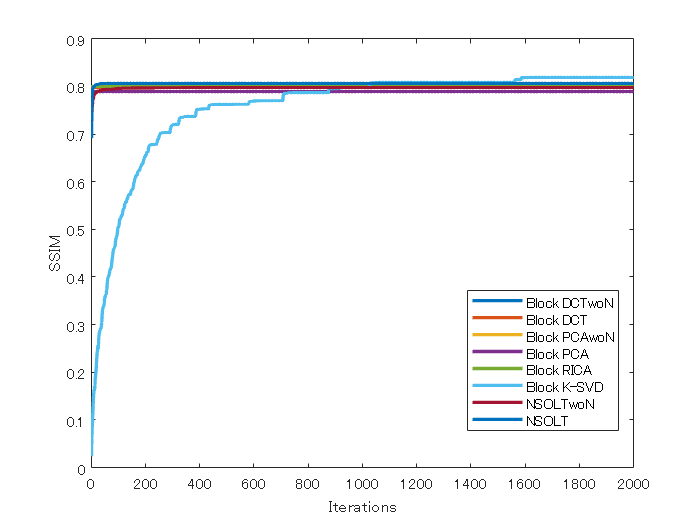

    import saivdr.dcnn.*
    %profile on
    for iIter = 1:nItersNsolt


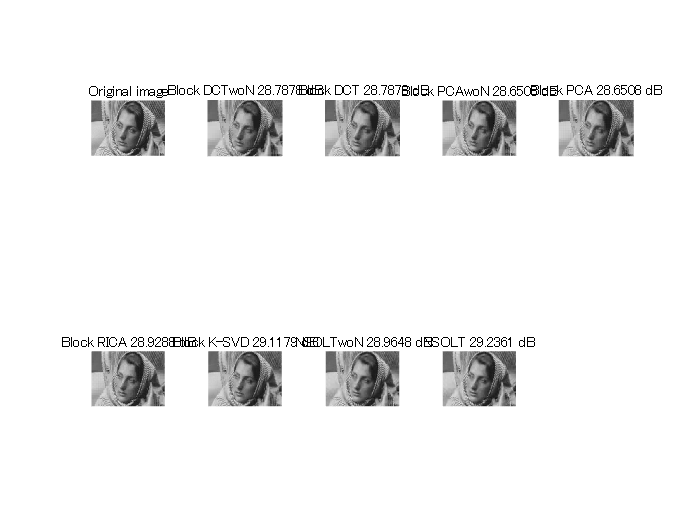

dicname = "Block DCTwoN"

dicname = "Block DCT"

dicname = "Block PCAwoN"

dicname = "Block PCA"

dicname = "Block RICA"

dicname = "Block K-SVD"

dicname = "NSOLTwoN"

dicname = "NSOLT"

        % Sparse approximation (Applied to produce an object of TransformedDatastore)
        coefimgds = transform(patchds, @(x) iht4patchds(x,analysisnet,synthesisnet,sparsityRatio));

        % Synthesis dictionary update
        trainlgraph = synthesislgraph.replaceLayer('Lv1_Out',...
            regressionLayer('Name','Lv1_Out'));
        trainednet = trainNetwork(coefimgds,trainlgraph,opts);

        % Analysis dictionary update (Copy parameters from synthesizer to analyzer)
        trainedlgraph = layerGraph(trainednet);
        analysislgraph = fcn_cpparamssyn2ana(analysislgraph,trainedlgraph);
        analysisnet = dlnetwork(analysislgraph);

        % Check the adjoint relation (perfect reconstruction)
        checkadjointrelation(analysislgraph,trainedlgraph,nLevels,szPatchTrn);

        % Replace layer
        synthesislgraph = trainedlgraph.replaceLayer('Lv1_Out',...
            nsoltIdentityLayer('Name','Lv1_Out'));
        synthesisnet = dlnetwork(synthesislgraph);


    end
    %profile off
    %profile viewer

#### 訓練ネットワークの保存

    import saivdr.dcnn.*
    synthesislgraph = layerGraph(synthesisnet);
    analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);
    analysisnet = dlnetwork(analysislgraph);
    save(sprintf('../results/nsoltdictionary_%s',datetime('now','Format','yyyyMMddHHmmssSSS')),'analysisnet','synthesisnet','nLevels')
end

analysislgraph = layerGraph(analysisnet);
synthesislgraph = layerGraph(synthesisnet);

figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

#### 要素画像の表示

import saivdr.dcnn.*

figure

atomicimshow(synthesisnet,[],2^(nLevels-1))
title('Atomic images of trained NSOLT')

### 推論用NSOLTネットワークの構築


% Assemble analyzer
analysislgraph4predict = analysislgraph;
analysislgraph4predict = analysislgraph4predict.replaceLayer('Image input',...
    imageInputLayer(szOrg,'Name','Image imput','Normalization','none'));
for iLayer = 1:height(analysislgraph4predict.Layers)
    layer = analysislgraph4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        analysislgraph4predict = analysislgraph4predict.replaceLayer(layer.Name,...
            regressionLayer('Name',layer.Name));
    end
end
analysisnet4predict = assembleNetwork(analysislgraph4predict);

% Assemble synthesizer
synthesislgraph4predict = synthesislgraph;
synthesislgraph4predict = synthesislgraph4predict.replaceLayer('Lv1_Out',...
    regressionLayer('Name','Lv1_Out'));
for iLayer = 1:height(synthesislgraph4predict.Layers)
    layer = synthesislgraph4predict.Layers(iLayer);
    if contains(layer.Name,'Ac feature input')
        iLv = str2double(layer.Name(3));
        sbSize = szOrg.*(decFactor.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize (sum(nChannels)-1)],'Name',layer.Name,'Normalization','none');
        synthesislgraph4predict = synthesislgraph4predict.replaceLayer(...
            layer.Name,newlayer);
    elseif contains(layer.Name,sprintf('Lv%0d_Dc feature input',nLevels))
        iLv = str2double(layer.Name(3));
        sbSize = szOrg.*(decFactor.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize 1],'Name',layer.Name,'Normalization','none');
        synthesislgraph4predict = synthesislgraph4predict.replaceLayer(...
            layer.Name,newlayer);
    end
end
synthesisnet4predict = assembleNetwork(synthesislgraph4predict);  

#### 随伴関係（完全再構成）の確認

NSOLTはパーセバルタイト性を満たす．

u = rand(szOrg,'single');
[s{1:nLevels+1}] = analysisnet4predict.predict(u);
v = synthesisnet4predict.predict(s{1:nLevels+1});
assert(mse(u,v)<1e-9)

#### NSOLTによる合成処理とその随伴処理の定義

nsoltconfig.nLevels = nLevels;
szCoefs = zeros(nLevels+1,3);
for iLevel = 1:nLevels+1
    s_iLevel = s{iLevel};
    szCoefs(iLevel,1) = size(s_iLevel,1);
    szCoefs(iLevel,2) = size(s_iLevel,2);
    szCoefs(iLevel,3) = size(s_iLevel,3);
end
nsoltconfig.szCoefs = szCoefs;
syn_nsolt = @(x) synthesisnsolt(x,synthesisnet4predict,nsoltconfig);
adj_nsolt = @(y) analysisnsolt(y,analysisnet4predict,nsoltconfig);

#### 随伴関係の確認

x = adj_nsolt(y);
v = randn(size(x));
u = syn_nsolt(v);
assert(abs(dot(y(:),u(:))-dot(x(:),v(:)))<1e-3)

## 繰返しハード閾値処理(IHT)によるスパース近似の比較

#### 辞書の準備

blkdctwon  = { syn_blkdct,  adj_blkdct,  "Block DCTwoN", false };
blkdct  = { syn_blkdct,  adj_blkdct,  "Block DCT", true };
blkpcawon  = { syn_blkpca,  adj_blkpca,  "Block PCAwoN", false };
blkpca  = { syn_blkpca,  adj_blkpca,  "Block PCA", true };
blkrica = { syn_blkrica, adj_blkrica, "Block RICA", true };
blkksvd = { syn_blkksvd, adj_blkksvd, "Block K-SVD", true };
nsoltwon   = { syn_nsolt,   adj_nsolt,   "NSOLTwoN", false };
nsolt = { syn_nsolt,   adj_nsolt,   "NSOLT", true };
dicset  = { blkdctwon, blkdct, blkpcawon, blkpca, blkrica, blkksvd, nsoltwon, nsolt };
nDics   = length(dicset);

#### IHT

         
$$\mathbf{x}^{(t+1)}\leftarrow \mathcal{H}_{BK}\left(\mathbf{x}^{(t)}+\mu^{(t)}\hat{\mathbf{D}}^\textsf{T}\left(\mathbf{y}-\hat{\mathbf{D}}\mathbf{x}^{(t)}\right)\right)$$


        
$$t\leftarrow t+1$$


-  T. Blumensath and M. E. Davies, "Normalized Iterative Hard Thresholding: Guaranteed Stability and Performance," in IEEE Journal of Selected Topics in Signal Processing, vol. 4, no. 2, pp. 298-309, April 2010, doi: 10.1109/JSTSP.2010.2042411.

nItersIht = 2000;

% 平均値を引いた画像を用意（近似後に平均値を加算）
ymean = mean(yorg,"all");
y = yorg - ymean;
% 準備
c = 1e-3;
kappa = 1.1/(1-c);
nCoefs = floor(sparsityRatio*prod(szOrg));
psnrs = zeros(nItersIht,nDics);
ssims = zeros(nItersIht,nDics);
yaprxs = cell(1,nDics);
% 繰り返し処理
for iDic = 1:nDics
    dic_ = dicset{iDic};
    synproc = dic_{1};
    adjproc = dic_{2};
    dicname = dic_{3};
    isStepSizeNormalized = dic_{4};
    % IHT
    display(dicname)
    s = adjproc(y); % D^Ty
    xt = zeros(size(s),'like',s); % x1 = 0;
    if isStepSizeNormalized % 正規化あり
        suppt = find(hardthresh(s,nCoefs)); % Γ1 = supp(H_K(D^Ty))
        maskt = (abs(s)~=0);
    end
    for iIter=1:nItersIht
        % Gradient descent
        gt = adjproc(y-synproc(xt)); % g = D^T(y-Dxn)
        if ~isStepSizeNormalized % 正規化なし
            mu = (1-c);
            xtp1 = hardthresh(xt+mu*gt,nCoefs);
        else % 正規化あり
            ggt = gt(suppt); % g_Γn
            ugt = synproc(maskt.*gt); % D_Γn^T g_Γn
            mu = (ggt.'*ggt)/(ugt(:).'*ugt(:));
            ttp1 = hardthresh(xt+mu*gt,nCoefs); % ~xn+1 = H_K(xn + μn gn)
            supptp1 = find(ttp1); % Γn+1 = supp(~xn+1)
            if length(supptp1)==length(suppt) && all(supptp1==suppt)
                xtp1 = ttp1; % xn+1 = ~xn+1
            else
                dxt = ttp1-xt; % ~xn+1 - xn
                omega = (1-c)*(norm(dxt,'fro')/norm(synproc(dxt),'fro'))^2;
                if mu <= omega
                    xtp1 = ttp1; % xn+1 = ~xn+1
                else
                    while mu > omega
                        mu = mu/(kappa*(1-c));
                        ttp1 = hardthresh(xt+mu*gt,nCoefs); % ~xn+1 = H_K(xn + μn gn)
                        dxt = ttp1-xt; % ~xn+1 - xn
                        omega = (1-c)*(norm(dxt,'fro')/norm(synproc(dxt),'fro'))^2;
                    end
                    supptp1 = find(ttp1);  % Γn+1 = supp(~xn+1)
                    xtp1 = ttp1; % xn+1 = ~xn+1
                end
            end
            % Update
            suppt = supptp1;
            maskt = zeros(size(maskt),'like',maskt);
            maskt(suppt) = 1;
        end
        xt = xtp1;
        % Monitoring
        checkSparsity = nnz(xt)/prod(szOrg)<=sparsityRatio;
        assert(checkSparsity)
        yaprx_ = synproc(xt);
        psnr_ = psnr(cast(yaprx_,'like',y),y);
        ssim_ = ssim(cast(yaprx_,'like',y),y);
        psnrs(iIter,iDic) = psnr_;
        ssims(iIter,iDic) = ssim_;
        %fprintf("IHT(%d) PSNR: %6.4f\n",iIter,psnr_);
    end
    yaprxs{iDic} = yaprx_ + ymean;
end

## 近似結果の表示

dicnames = [blkdctwon{3},blkdct{3},blkpcawon{3},blkpca{3},blkrica{3},blkksvd{3},nsoltwon{3},nsolt{3}];
psnrtbl = array2table(psnrs,'VariableNames',dicnames);
psnrtbl = horzcat(table((1:nItersIht).','VariableNames',"Iterations"),psnrtbl);
ssimtbl = array2table(ssims,'VariableNames',dicnames);
ssimtbl = horzcat(table((1:nItersIht).','VariableNames',"Iterations"),ssimtbl);

% PSNR のグラフ
figure
plot(psnrtbl,"Iterations",dicnames,'LineWidth',2)
ylabel('PSNR [dB]')
legend('Location','best')
% SSIM のグラフ
figure
plot(ssimtbl,"Iterations",dicnames,'LineWidth',2)
ylabel('SSIM')
legend('Location','best')



% 原画像の表示
figure
tiledlayout(2,ceil((nDics+1)/2))
nexttile
imshow(yorg)
title("Original image")
% 近似画像の表示
for idx = 1:nDics
    yaprx = yaprxs{idx};
    dicname = dicnames(idx)
    file_yaprx = "../results/yaprx_" + replace(lower(dicname),' ','_') +".png";
    imwrite(yaprx,file_yaprx)
    %
    nexttile
    imshow(yaprxs{idx})
    title(dicname+" "+num2str(psnrs(end,idx))+" dB")
end

## 【関数定義】

#### NSOLT合成処理関数

function y = synthesisnsolt(x,synthesisnet4predict,config)
nLevels = config.nLevels;
szCoefs = config.szCoefs;
s = cell(1,nLevels+1);
sidx = 1;
for iLevel = 1:nLevels+1
    sz_iLevel = szCoefs(iLevel,:);
    eidx = sidx+prod(sz_iLevel)-1;
    x_iLevel = x(sidx:eidx);
    s{iLevel} = reshape(x_iLevel,sz_iLevel);
    sidx = eidx+1;
end
y = synthesisnet4predict.predict(s{1:nLevels+1});
end


#### NSOLT分析処理関数

function x = analysisnsolt(y,analysisnet4predict,config)
nLevels = config.nLevels;
szCoefs = config.szCoefs;
[s{1:nLevels+1}] = analysisnet4predict.predict(y);
nCoefs = sum(prod(szCoefs,2),1);
%x = [];
x = zeros(nCoefs,1);
sidx = 1;
for iLevel = 1:nLevels+1
    %x = [x; s{iLevel}(:)];
    eidx = sidx - 1 + prod(szCoefs(iLevel,:));
    x(sidx:eidx) = s{iLevel}(:);
    sidx = eidx + 1;
end
end

#### ハード閾値処理

function y = hardthresh(x,K)
v = sort(abs(x(:)),'descend');
thk = v(K);
y = (abs(x)>thk).*x;
end

#### 深層学習配列に対する繰返しハード閾値処理(IHT)のバッチ処理

function newdata = iht4patchds(oldtbl,analyzer,synthesizer,sparsityRatio)
% IHT for InputImage in randomPatchExtractionDatastore
%
nInputs = length(synthesizer.InputNames);

% Apply IHT process for every input patch
restbl = removevars(oldtbl,'InputImage');
dlv = dlarray(cat(4,oldtbl.InputImage{:}),'SSCB');
[~,dlcoefs{1:nInputs}] = iht4dlarray(dlv,analyzer,synthesizer,sparsityRatio);
coefs = cellfun(@(x) permute(num2cell(extractdata(x),1:3),[4 1 2 3]),dlcoefs,'UniformOutput',false);
%
nImgs = length(oldtbl.InputImage);
coefarray = cell(nImgs,nInputs);
for iImg = 1:nImgs
    for iInput = 1:nInputs
        coefarray{iImg,iInput} = coefs{iInput}{iImg};
    end
end
% Output as a cell in order to make multiple-input datastore
newdata = [ coefarray table2cell(restbl) ];
end

#### 深層学習配列に対する繰返しハード閾値処理(IHT)

function [dly,varargout] = iht4dlarray(dlx,analyzer,synthesizer,sparsityRatio)
% IHT Iterative hard thresholding
%
nInputs = length(synthesizer.InputNames);
szBatch = size(dlx,4);

% Iterative hard thresholding w/o normalization
% (A Parseval tight frame is assumed)
gamma = (1.-1e-3);
nIters = 10;
nCoefs = floor(sparsityRatio*numel(dlx(:,:,:,1)));
[dlcoefs{1:nInputs}] = analyzer.predict(dlarray(zeros(size(dlx),'like',dlx),'SSCB'));
% IHT
for iter=1:nIters
    % Gradient descent
    dly = synthesizer.predict(dlcoefs{1:nInputs});
    [grad{1:nInputs}] = analyzer.predict(dlx-dly);
    dlcoefs = cellfun(@(x,y) x+gamma*y,dlcoefs,grad,'UniformOutput',false);
    % Hard thresholding
    coefvecs = cellfun(@(x) extractdata(reshape(x,[],szBatch)),dlcoefs,'UniformOutput',false);
    srtdabscoefs = sort(abs(cell2mat(coefvecs.')),1,'descend');
    thk = reshape(srtdabscoefs(nCoefs,:),1,1,1,szBatch);
    dlcoefs = cellfun(@(x) (abs(x)>thk).*x,dlcoefs,'UniformOutput',false);
    % Monitoring
    %checkSparsity =...
    %nnz(srtdabscoefs>srtdabscoefs(nCoefs,:))/numel(dlx)<=sparsityRatio;
    %assert(checkSparsity)
    %fprintf("IHT(%d) MSE: %6.4f\n",iter,mse(dlx,dly));
end
varargout = dlcoefs;
end

#### NSOLTネットワークの随伴関係の確認

function checkadjointrelation(analysislgraph,synthesislgraph,nLevels,szInput)
import saivdr.dcnn.*
x = rand(szInput,'single');
% Assemble analyzer
analysislgraph4predict = analysislgraph;
for iLayer = 1:length(analysislgraph4predict.Layers)
    layer = analysislgraph4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        analysislgraph4predict = analysislgraph4predict.replaceLayer(layer.Name,...
            regressionLayer('Name',layer.Name));
    end
end
analysisnet4predict = assembleNetwork(analysislgraph4predict);

% Assemble synthesizer
synthesislgraph4predict = synthesislgraph;
synthesisnet4predict = assembleNetwork(synthesislgraph4predict);

% Analysis and synthesis process
[s{1:nLevels+1}] = analysisnet4predict.predict(x);
if isvector(s{end-1})
    s{end-1} = permute(s{end-1},[1,3,2]);
end
y = synthesisnet4predict.predict(s{:});

% Evaluation
display("MSE: " + num2str(mse(x,y)))
end

#### 直交マッチング追跡関数の定義

function x = omp(y,Phi,nCoefs)
% Initializaton
nDims = size(Phi,1);
nAtoms = size(Phi,2);
e = ones(nAtoms,1);
a = zeros(nAtoms,1);
g = zeros(nAtoms,1);
x = zeros(nAtoms,1);
v = zeros(nDims,1);
r = y - v;
supp = [];
k = 0;
while k < nCoefs
    % Matching process
    rr = r.'*r;
    for m = setdiff(1:nAtoms,supp)
        d = Phi(:,m);
        g(m) = d.'*r; % γm=<dm,r>
        a(m) = g(m)/(d.'*d); % Normalize αm=γm/||dm||^2
        e(m) = rr - g(m)*a(m); % <r-dm/||dm||^2,r>
    end
    % Minimum value search (pursuit)
    [~,mmin]= min(e);
    % Update the support
    supp = union(supp,mmin);
    subPhi = Phi(:,supp);
    x(supp) = pinv(subPhi) * y;
    % Synthesis process
    v = Phi*x;
    % Residual
    r = y - v;
    % Update
    k = k + 1;
end
end

#### NSOLTネットワークからのツリーレベル情報の抽出

function nLevels = extractnumlevels(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expidctlayer = '^Lv\d+_E0~?$';
nLevels = 0;
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expidctlayer,'once'))
        nLevels = nLevels + 1;
    end
end
end

#### NSOLTネットワークからのストライド情報の抽出

function decFactor = extractdecfactor(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        decFactor = layer.DecimationFactor;
    end
end
end

#### NSOLTネットワークからのチャネル数情報の抽出

function nChannels = extractnumchannels(nsoltnet)
import saivdr.dcnn.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(nsoltnet.Layers);
for iLayer = 1:nLayers
    layer = nsoltnet.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        nChannels = layer.NumberOfChannels;
    end
end
end

© Copyright, 2023, Shogo MURAMATSU, All rights reserved.